clc;clear all;close all;
s=tf('s');
% A=[1 2;2 4];
% B=[1;3];
% C=[1 2];
% D=[5];
% G=ss(A,B,C,D);

% KPID=pidtune(G,'PID');
% GCL=feedback(G*KPID,1);
% %step(GCL,40);hold on
z0=rand(2,1);


% legend('opt','PIDtune')

[zopt,Jopt]=fmincon(@(z)costo(z,2),z0,[],[],[],[],[],[],@restr)


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


zopt =     0.8342
    1.0085


Jopt = 290.1725

A=[1 2;2 4];
B=[1;7];
C=[1 -1];
D=[5];
G=ss(A,B,C,D);
K=[zopt(1) zopt(2)];
Kr=(-(C-D*K)*((A-B*K)\B)+D)^-1;
GCL=ss(A-B*K,B*Kr,C-D*K,D*Kr);
pole(GCL)

ans =   -1.4468 + 1.0985i
  -1.4468 - 1.0985i


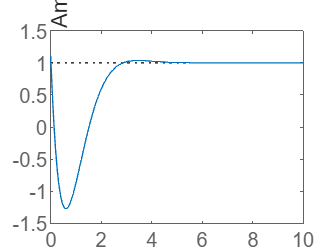

step(GCL,10);

function J=costo(z,i)
    k1=z(1);
    k2=z(2);
    s=tf('s');
    A=[1 2;2 4];
    B=[1;7];
    C=[1 -1];
    D=[5];
    G=ss(A,B,C,D);
    K=[k1 k2];
    Kr=(-(C-D*K)*((A-B*K)\B)+D)^-1;
    GCL=ss(A-B*K,B*Kr,C-D*K,D*Kr);
    tv=0:0.01:4;
    [Y,T]=step(GCL,tv);
    Yref=1;
    if(i==1)
        J=sum(abs(Y-Yref));
    elseif(i==2)
        J=sum(abs(Y-Yref).*T);
    elseif(i==3)
        J=sum((Y-Yref).^2);
    elseif(i==4)
        J=sum(((Y-Yref).^2).*T);
    end
end

function [c,c_eq]=restr(z)
    k1=z(1);
    k2=z(2);
    s=tf('s');
    A=[1 2;2 4];
    B=[1;7];
    C=[1 -1];
    D=[5];
    G=ss(A,B,C,D);
    K=[k1 k2];
    Kr=(-(C-D*K)*((A-B*K)\B)+D)^-1;
    GCL=ss(A-B*K,B*Kr,C-D*K,D*Kr);
    data=stepinfo(GCL);
    OS=data.Overshoot;
    if(isnan(OS))OS=1000;end
    c=[OS-10];
    c_eq=[];
end